# **完成**

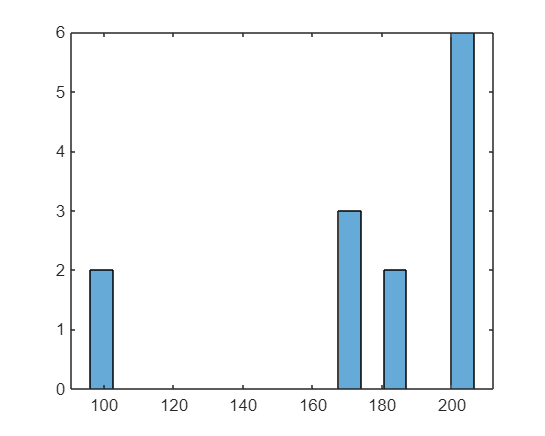

%執行檔
c=imread('cameraman.tif');
hc=hough2(c);
[r,theta]=find(hc>80);
r(theta<100)=[];
theta(theta<100)=[];
h=histogram(theta,17);

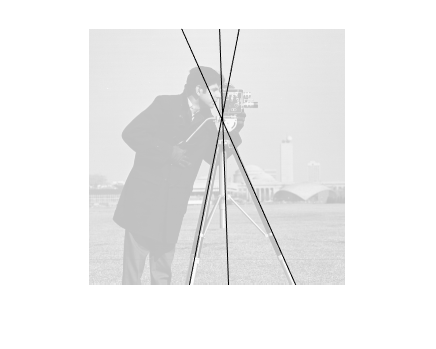

num = h.Values;

val=max(num);
n1=1;
for i=1:find(num==val)-1
    n1=n1+num(i);
end
val2=max(num(num<val));

n2=1;
for i=1:find(num==val2)-1
    n2=n2+num(i);
end

str=find(r==min(r(abs(theta-180)<10)));

c2=imadd(imdivide(c,4),190);
imshow(c2)
houghline(c2,r(n1),theta(n1))
houghline(c2,r(n2),theta(n2))
houghline(c2,r(str),theta(str))